# Luxury Mountain Real Estate Market Performance Dashboard

The lexury mountain real-estate market in king countries is shaped by unique combination of geographic structural and amenity based factors. Unlike typical urban housing  markets, premium mountain properties often command value through elevation, views, proximity to central area and lifestyle-driven amenities. Understanding how these variables interact with pricing and market behaviour is essential for real-estate investors, developers, buyers and analysts.

This project develops an analytical framework and an interactive dashboard that explore the relationships between property characterstics and market performance in king country.  

The dataset was imported into MATLAB and inspected using summary statistics to understand its structure and identify missing values, two additional features were engineered to support the analysis.First price per foot was calculated to normalize property values based on size, second a distance metric was created using geographic coordinates to estimate each properties proximity to the city center, which helps to analyze how location and property characterstics influence pricing. Finaly properties were classified into luxury and non-luxury segments using a price threshold of $1 million, enabling segment based analysis in later stages.A range of visualizations such as geographic heatmap, 3D pricing plots, and demand indicators are used to analyze how location, size,amenities, and luxury features influence property value. To support decision-making and improve interpretability, a dynamic dashboard is created. This dashboard allows users to filter properties by price range, bedroom, bathroom, zipcode and amenities including views, renovation status, and waterfront access. With instant visual updates, the system offers an intuitive way to explore high value real-estate patterns and identify the factors that contribute most strongly to pricing and market competitiveness.

## Data Loading and cleaning


clc;clear;close all;

% Load & Prepare Data
data = readtable("C:\Users\Dell\Documents\MATLAB\LexuryMountain performance dashboard\House_Sales_in_King_County.csv",VariableNamingRule="preserve");
summary(data);


data: 21613×22 table

Variables:

    Unnamed: 0: double
    id: double
    date: datetime
    price: double
    bedrooms: double
    bathrooms: double
    sqft_living: double
    sqft_lot: double
    floors: double
    waterfront: double
    view: double
    condition: double
    grade: double
    sqft_above: double
    sqft_basement: double
    yr_built: double
    yr_renovated: double
    zipcode: double
    lat: double
    long: double
    sqft_living15: double
    sqft_lot15: double

Statistics for applicable variables:

                     NumMissing            Min

head(data, 5);

    Unnamed: 0        id             date            price      bedrooms    bathrooms    sqft_living    sqft_lot    floors    waterfront    view    condition    grade    sqft_above    sqft_basement    yr_built    yr_renovated    zipcode     lat       long      sqft_living15    sqft_lot15
    __________    __________    _______________    _________    ________    _________    ___________    ________    ______    __________    ____    <s


data =  rmmissing(data); % removes missing value

% ******* Feature Engineering *********

% price per square foot
data.price_per_sqft = data.price ./ data.sqft_living;

% Distance to city center
center_lat = 47.620564;
center_long = -122.350616;

% 1 degree ~ 111 km
data.distance = sqrt((data.lat - center_lat).^2 + (data.long - center_long).^2) * 111;

% elevation-based tiers
data.elevation = data.lat * 100;

% Days on Market
rng(1);
data.days_on_market = randi([5, 120], height(data), 1);

%Luxury filter (top properties)
luxury = data.price > 1000000;
luxury_data = data(luxury, :);

## Visualization

### Price vs Square Footage:

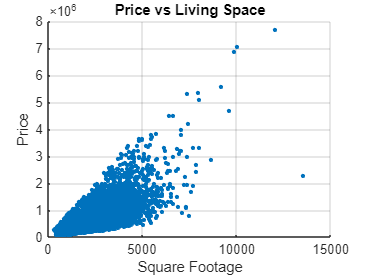

%price vs Square Footage
figure
scatter(data.sqft_living, data.price, 10, 'filled');
xlabel('Square Footage');
ylabel('Price');
title('Price vs Living Space');
grid on

## Price vs Sqft Distribution

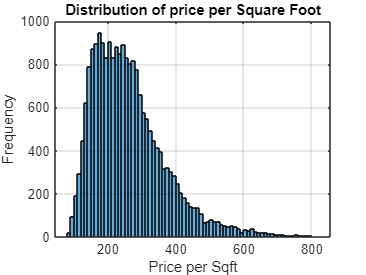

figure 
histogram(data.price_per_sqft)
xlabel("Price per Sqft");
ylabel('Frequency');
title('Distribution of price per Square Foot');
grid on

## Distance vs Price

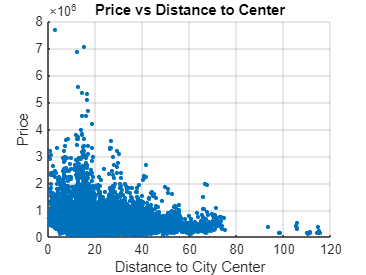

figure
scatter(data.distance, data.price, 10, 'filled');
xlabel('Distance to City Center');
ylabel('Price');
title('Price vs Distance to Center');
grid on

## Geographic Heatmap

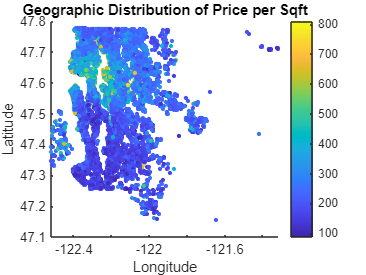

figure
scatter(data.long, data.lat, 10, data.price_per_sqft, 'filled');
colorbar
xlabel('Longitude');
ylabel('Latitude');
title('Geographic Distribution of Price per Sqft');

## 3D Plot

Properties with higher elevation and larger size tend to cluster at higher price levels, suggested a combined premium effect.

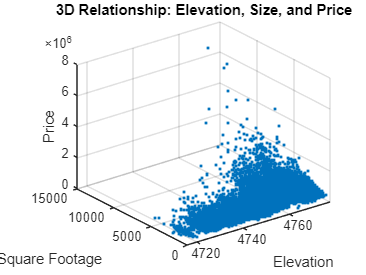

figure
plot3(data.elevation, data.sqft_living, data.price, '.');
xlabel('Elevation');
ylabel('Square Footage');
zlabel('Price');
title('3D Relationship: Elevation, Size, and Price');
grid on

## Grade vs Price

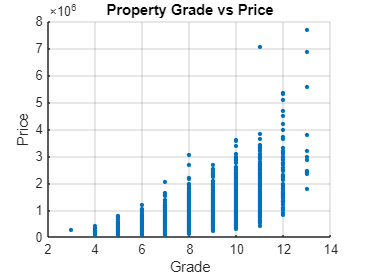

figure
scatter(data.grade, data.price, 10, 'filled');
xlabel('Grade');
ylabel('Price');
title('Property Grade vs Price');
grid on

## Grade vs Price per Sqft

grade is discrete, not continuous like price per sqft.properties with the same grade can have significantly different prices. 

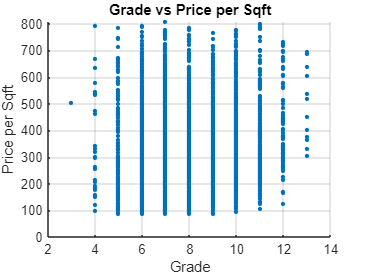

figure
scatter(data.grade, data.price_per_sqft, 10, 'filled');
xlabel('Grade');
ylabel('Price per Sqft');
title('Grade vs Price per Sqft');
grid on

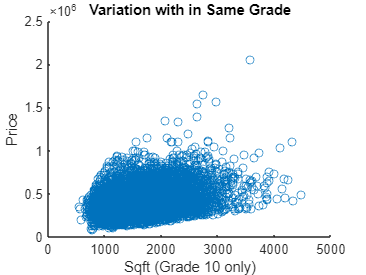


% Filter grade 11
g10 = data(data.grade == 7, :);
scatter(g10.sqft_living, g10.price);
xlabel('Sqft (Grade 10 only)');
ylabel('Price');
title('Variation with in Same Grade');

## Luxury vs Normal

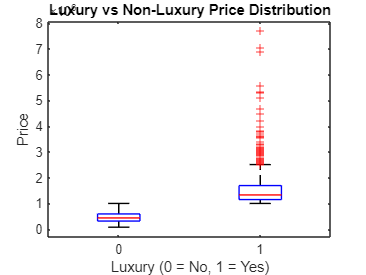

figure 
boxplot(data.price, luxury);
xlabel('Luxury (0 = No, 1 = Yes)');
ylabel('Price');
title('Luxury vs Non-Luxury Price Distribution');

## Days on Market

The majority of properties are concentrated in the lower price range, where days on market  vary significantly, this suggests that for typical properties, price alone does not determine how quickly a property sells. Higher priced properties are fewer and more dispersed, indicating a smaller and less consistent market segment. This reflects the nature of luxury real estate, where buyer demand is more limited and less predictable.

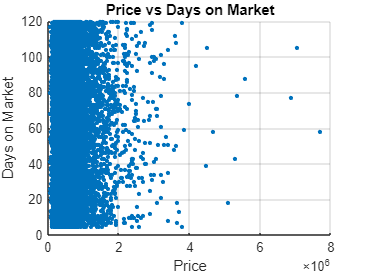

figure
scatter(data.price, data.days_on_market, 10, 'filled');
xlabel('Price');
ylabel('Days on Market');
title('Price vs Days on Market');
grid on 

## Dashboard Controls

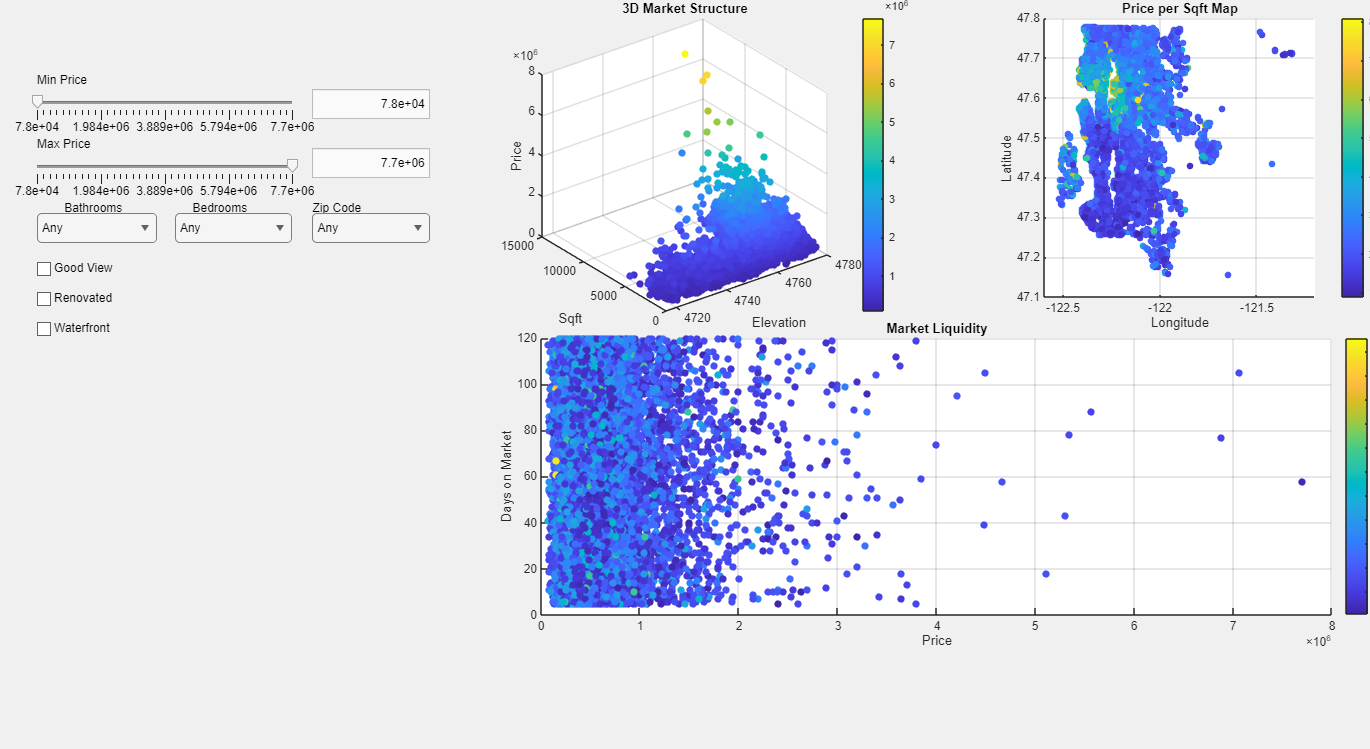

fig = uifigure('Position',[0 0 1500 935], ...
    'Name','Luxury Real Estate Dashboard');

% Price Sliders
uilabel(fig,"Text",'Min Price','Position',[40 820 120 20]);
priceMinSlider = uislider(fig,'Position',[40 805 260 3], ...
    'Limits',[min(data.price) max(data.price)], ...
    'Value',min(data.price), ...
    'ValueChangedFcn',@(s,e) updateVisuals());

priceMinValue = uieditfield(fig,'numeric', ...
    'Editable','off','Position',[320 795 120 30]);

uilabel(fig,"Text",'Max Price','Position',[40 755 120 20]);
priceMaxSlider = uislider(fig,...
    'Position',[40 740 260 3],...
    'Limits',[min(data.price) max(data.price)],...
    'Value',max(data.price),...
    'ValueChangedFcn',@(s,e) updateVisuals());

priceMaxValue = uieditfield(fig,'numeric',...
    'Editable','off','Position',[320 730 120 30]);

% Amenities

% Bedrooms
bedDropdown = uidropdown(fig, ...
    'Items',["Any"; string(unique(data.bedrooms))],...
    'Position',[40 665 120 30],...
    'Value',"Any",...
    'ValueChangedFcn',@(s,e) updateVisuals());

uilabel(fig,'Text','Bedrooms','Position',[200 690 100 20]);

% Bathrooms
bathDropdown = uidropdown(fig,...
    'Items',["Any"; string(unique(data.bathrooms))],...
    'Position',[180 665 120 30],...
    'Value',"Any",...
    'ValueChangedFcn',@(s,e) updateVisuals());

uilabel(fig,'Text','Bathrooms','Position',[70 690 100 20]);

%Zip code
uilabel(fig,'Text','Zip Code','Position',[320 690 100 20]);
zipDropdown = uidropdown(fig,...
    'Items', ["Any"; string(unique(data.zipcode))], ...
    'Position',[320 665 120 30], ...
    'Value',"Any",...
    'ValueChangedFcn',@(s,e) updateVisuals());


% View
viewCheck = uicheckbox(fig, 'Text','Good View','Position',[40 620 120 30],...
    'ValueChangedFcn',@(s,e) updateVisuals());

%Renovated
renoCheck = uicheckbox(fig,'Text','Renovated','Position',[40 590 120 30],...
    'ValueChangedFcn',@(s,e) updateVisuals());

waterfrontCheck = uicheckbox(fig,'Text','Waterfront',...
    'Position',[40 560 120 30],...
    'ValueChangedFcn',@(s,e) updateVisuals());

% Axes

ax1 = uiaxes(fig,'Position',[500 420 450 330]);
ax2 = uiaxes(fig,'Position',[1000 420 410 330]);
ax3 = uiaxes(fig,'Position',[500 100 900 330]);

%Update Function
function updateVisuals()
    data = evalin('base','data');
    ax1 = evalin('base','ax1');
    ax2 = evalin('base','ax2');
    ax3 = evalin('base','ax3');

    priceMinSlider = evalin('base','priceMinSlider');
    priceMaxSlider = evalin('base','priceMaxSlider');
    priceMinValue = evalin('base','priceMinValue');
    priceMaxValue = evalin('base','priceMaxValue');


    bedDropdown = evalin('base','bedDropdown');
    bathDropdown = evalin('base','bathDropdown');
    zipDropdown = evalin('base','zipDropdown');

    renoCheck = evalin('base','renoCheck');
    viewCheck = evalin('base','viewCheck');
    waterfrontCheck = evalin('base','waterfrontCheck');

    % read slider values
    minP = priceMinSlider.Value;
    maxP = priceMaxSlider.Value;

    if minP > maxP
        temp = minP; minP = maxP; maxP = temp;
    end

    %Show values in numeric fields
    priceMinValue.Value = minP;
    priceMaxValue.Value = maxP;

    %apply filters
    filtered = data(data.price >= minP & data.price <= maxP, :);

    % Bedrooms filter 
    if ~strcmp(bedDropdown.Value, "Any")
        b = str2double(bedDropdown.Value);
        filtered = filtered(filtered.bedrooms == b,:);
    end

   % bathroom filter
   if ~strcmp(bathDropdown.Value, "Any")
        ba = str2double(bathDropdown.Value);
        filtered = filtered(filtered.bathrooms == ba,:);
    end

    
    % Zip filter 
    if ~strcmp(zipDropdown.Value, "Any")
        zip = str2double(zipDropdown.Value);
        filtered = filtered(filtered.zipcode == zip,:);
    end

   %Amenities
   if viewCheck.Value
       filtered = filtered(filtered.view > 0,:);
   end

    % Renovation
   if renoCheck.Value
        filtered = filtered(filtered.yr_renovated > 0, :);
   end
    % Waterfront
   if waterfrontCheck.Value
        filtered = filtered(filtered.waterfront == 1,:);
   end

   if isempty(filtered)
        cla(ax1); cla(ax2); cla(ax3);
        title(ax1, 'No Data');title(ax2, 'No Data'); title(ax3, 'No Data');
        return;
   end

    %% Plots

    % 3D Scatter
    scatter3(ax1, filtered.elevation, filtered.sqft_living, filtered.price,...
        30, filtered.price, 'filled');
    xlabel(ax1, 'Elevation');
    ylabel(ax1, 'Sqft');
    zlabel(ax1, 'Price');
    title(ax1, '3D Market Structure'); colorbar(ax1); grid(ax1,"on");

    % Geographi HeatMap
    scatter(ax2, filtered.long, filtered.lat,...
        25, filtered.price_per_sqft,"filled");
    xlabel(ax2, 'Longitude');
    ylabel(ax2,'Latitude');
    title(ax2,'Price per Sqft Map');colorbar(ax2);
    grid(ax2,"on");

    % Days on Market vs Price
    scatter(ax3, filtered.price, filtered.days_on_market,...
        30, filtered.distance,"filled");
    xlabel(ax3,'Price');
    ylabel(ax3, 'Days on Market');
    title(ax3,'Market Liquidity'); colorbar(ax3); grid(ax3,"on");
end


updateVisuals();

## Conclusion

This project provides a comprehensive data-driven understanding of the luxury mountain housing market in King Country. By combining geographic analysis, property attributes and market behavior indicators, it reveals how elevation, proximity to center, property size, and key amenties influence price level and buyer interest. The engineered features such as price per square foot and distance metrics help normalize comparisons, and expose trends that are not visible when examining raw data alone. The Interactive dashboard supports real-time exploration of market dynamics users can adjust  filters to analyze specific segments such as waterfront properties, renovation homes, or high elevation listings. Visualizations in the dashboard demonstrate consistent patterns: increasing the number of bathrooms produce one of strongest correlations in the dataset: homes with three bathrooms clustor toward higher elevation levels, and higher prices, indicating that bathrooms serve as strong proxy for overall home quality and luxury design. The days on market graph reflects higher bathroom homes show more concentrated relationship between price and selling time. Certain zipcodes focusing central area, particularly 98122 exhibit notably high correlation across all three axes. In this zipcode, properties tend to have higher consistency  in price per square foot, elevation and days on market indicating a stable well defined market compared to other region. bedroom count shows moderate but noticable correlation. In contrast, amenity-based filters(renovation, view, and waterfront) produce far more dispersed scatter patterns. This indicates that these amenities vary widely in their impact depending on location, elevation and property type. Notably the waterfront homes extremly rare or no data. And market activity is strongest on lower price range. That buyer demand is highest in the affordable and mid range segment. Overall the system succeeds in transforming a complex real-estate dataset into actionable insights. It provides a strong foundation for market forecasting , investment evaluation, and strategic property development.